% calculate the average fluorescence lifetime of autofluorescence
tau3=2.4922;
p3=0.2700;
tau4=0.4069;
p4=0.7300;
autofluo_lft=(tau3*tau3*p3+tau4*tau4*p4)/(tau3*p3+tau4*p4)

autofluo_lft = 1.8536

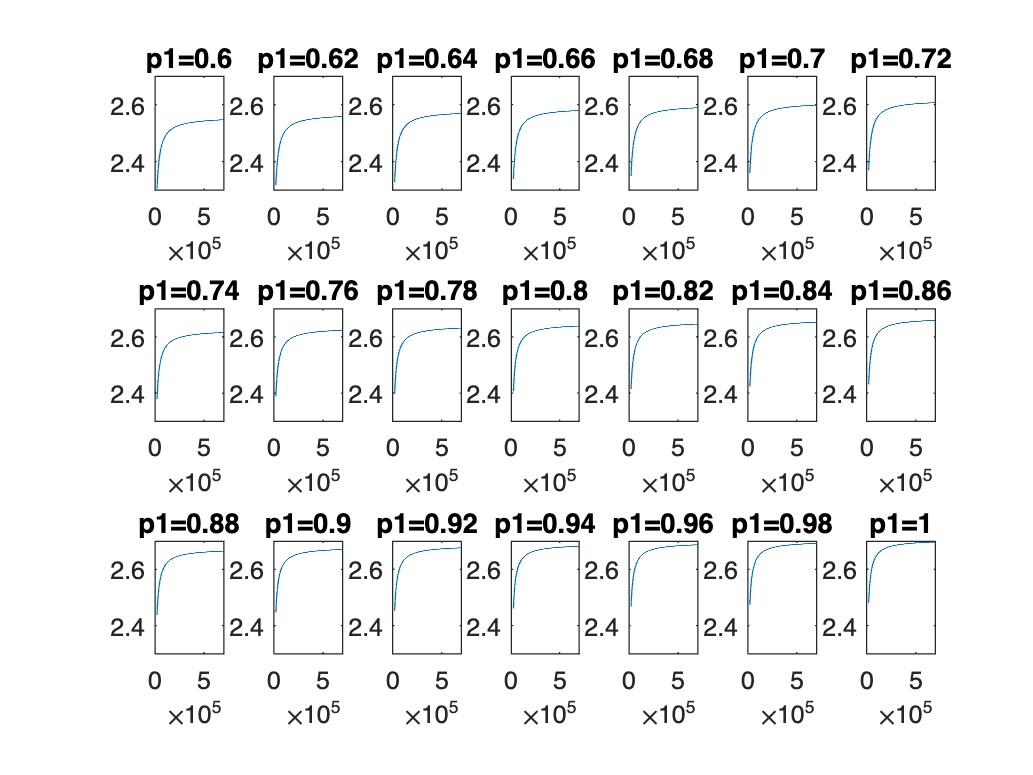

% analytically calculate the average fluorescence lifetime of
% autofluorescence and sensor fluorescence, given different ratio between
% autofluorescence and sensor fluorescence.
p1_samples=0.6:0.02:1.0;
AF=20000;
tau1=2.706;
tau2=0.2613;

sample_autofluo_ratio=1:0.05:35;
sample_sizes=sample_autofluo_ratio*AF;

mean_lfts_all=[];

for i=1:21
    p1=p1_samples(i);
    p2=1-p1;
    
    eval(['mean_lfts_',num2str(i),'=zeros(1,size(sample_autofluo_ratio,2));'])
    for j=1:size(sample_autofluo_ratio,2)
        ratio=sample_autofluo_ratio(j);
        mean_lft = (tau1*tau1*p1*ratio + tau2*tau2*p2*ratio + tau3*tau3*p3 + tau4*tau4*p4)/(tau1*p1*ratio + tau2*p2*ratio + tau3*p3+tau4*p4);
        
        eval(['mean_lfts_',num2str(i),'(j)=mean_lft;'])
    end
    subplot(3,7,i)
    eval(['plot(sample_sizes, mean_lfts_',num2str(i),')'])
    title(['p1=',num2str(p1_samples(i))])
    ylim([2.3 2.7])

    eval(['mean_lfts_all = [mean_lfts_all transpose(mean_lfts_',num2str(i),')];'])
end

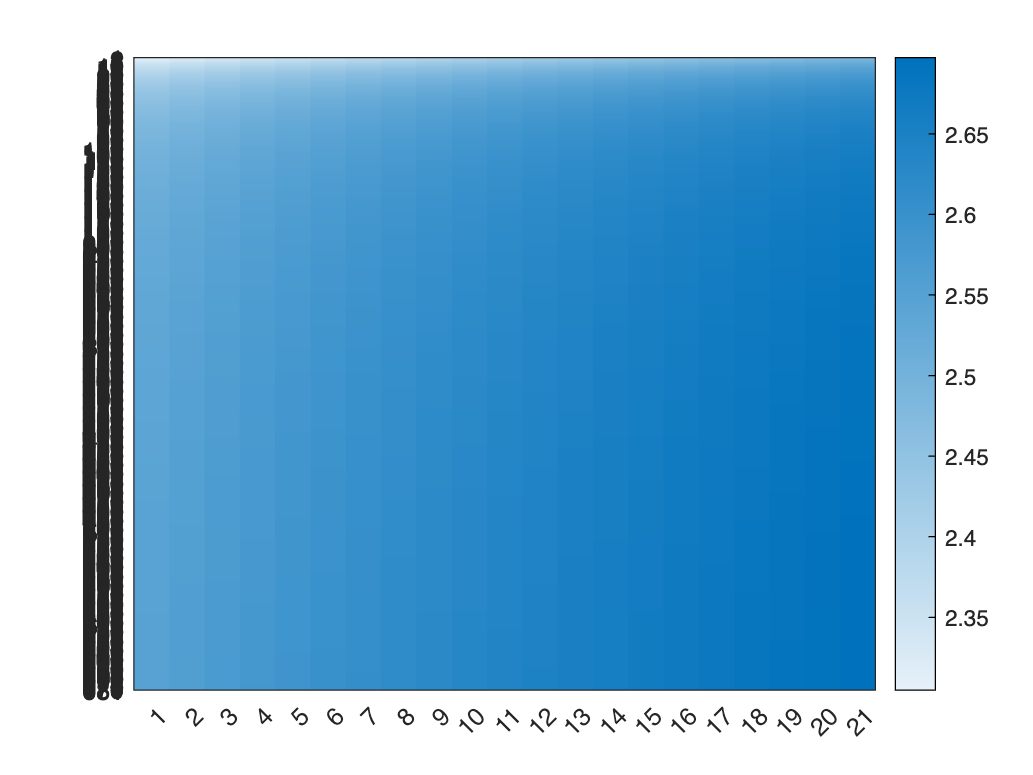


figure
heatmap(mean_lfts_all)
grid off

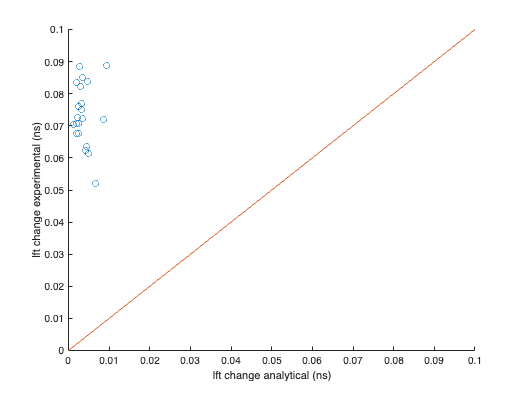

k=10;
lft_changes=[];
for i=1:size(photon_change_exp,2)
    photon_change=photon_change_exp(i);
    photon_baseline=photon_baseline_exp(i);
    lft_change=mean_lfts_10(photon_baseline/1000-19+photon_change/1000)-mean_lfts_10(photon_baseline/1000-19);
    lft_changes=[lft_changes;lft_change];
end

figure
scatter(lft_changes,lft_change_exp)
hold on
plot([0 0.1],[0 0.1])
xlabel('lft change analytical (ns)')
ylabel('lft change experimental (ns)')
hold off

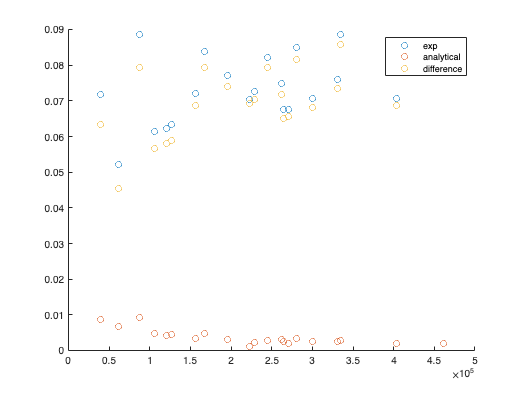


figure
scatter(photon_baseline_exp,lft_change_exp)
hold on
scatter(photon_baseline_exp,lft_changes)
hold on
scatter(photon_baseline_exp,lft_change_exp'-lft_changes)
legend('exp','analytical','difference')

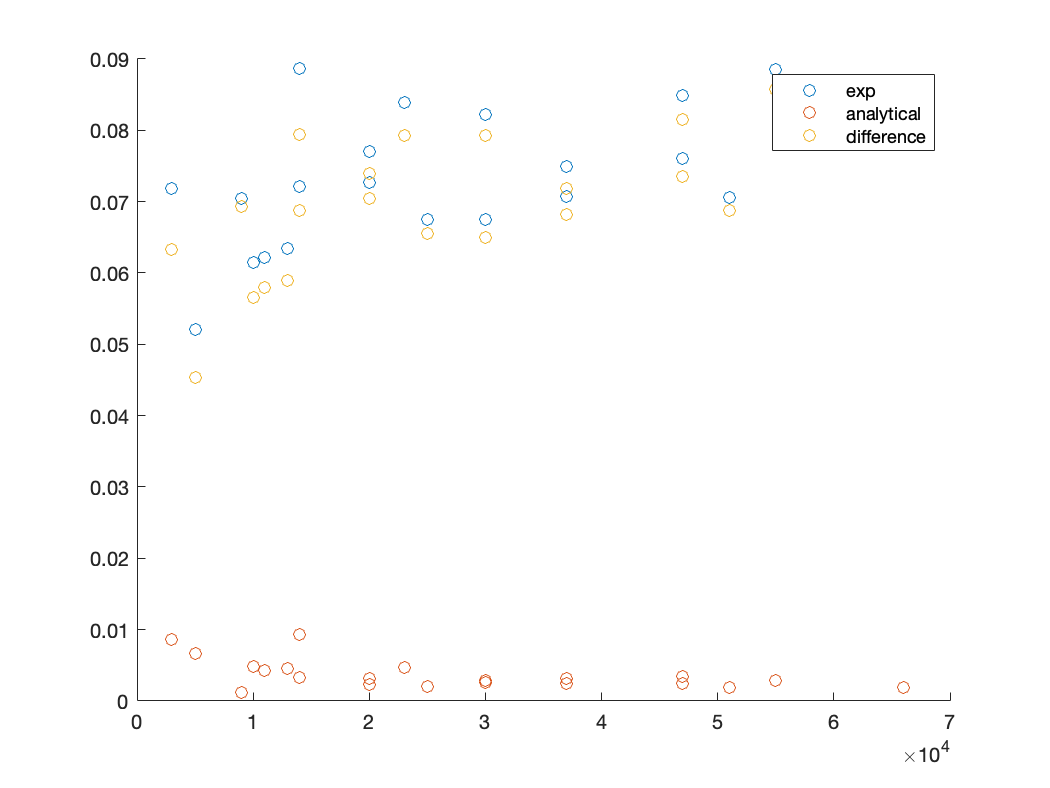


figure
scatter(photon_change_exp,lft_change_exp)
hold on
scatter(photon_change_exp,lft_changes)
hold on
scatter(photon_change_exp,lft_change_exp'-lft_changes)
legend('exp','analytical','difference')